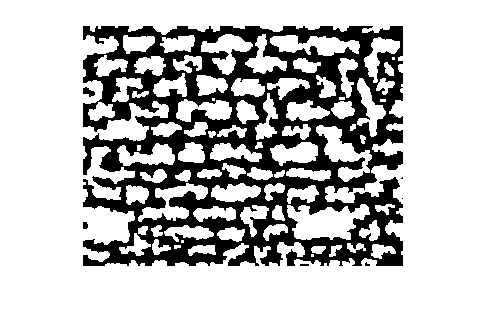

inverted = true;
img = imread("F\F1_IR000650.bmp");
%img = rgb2gray(img);

%filtro mediano
img = medfilt2(img);

%incremento contrasto immagine
max_value=max(img(:));
min_value=min(img(:));
img = imadjust(img, [min_value/255 max_value/255], [0.0 1.0]);

img=not(adaptivethreshold(img,floor(size(img,1)/12), 0.0, 0));
%img=imbinarize(img,"adaptive");

%rimozione buchi
[N, M] = size(img);
img_tmp = zeros(N+4, M+4);
img_tmp(3:N+2,3:M+2) = img;
img_tmp_filled = imfill(img_tmp, 'holes');
img = img_tmp_filled(3:N+2, 3:M+2);

if (inverted)
    %erosione
    img=imerode(img, strel('square',3));
    %dilatazione
    img=imdilate(img,strel('square',3));
else
    %dilatazione
    img=imdilate(img,strel('square',3));
    %erosione
    img=imerode(img, strel('square',3));
end

imshow(img)

result2=img;

imshow(img)

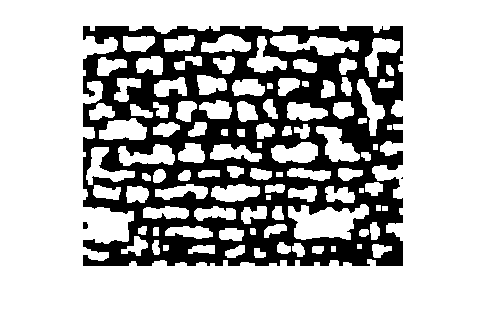

imshow(img)

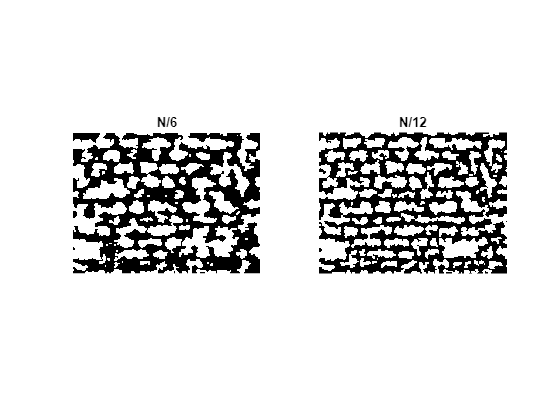

figure;
subplot(1,2,1);
imshow(result);
title("N/6")
subplot(1,2,2);
imshow(result2);
title("N/12")
saveas(gcf, 'subplot_immagini.bmp', 'bmp');

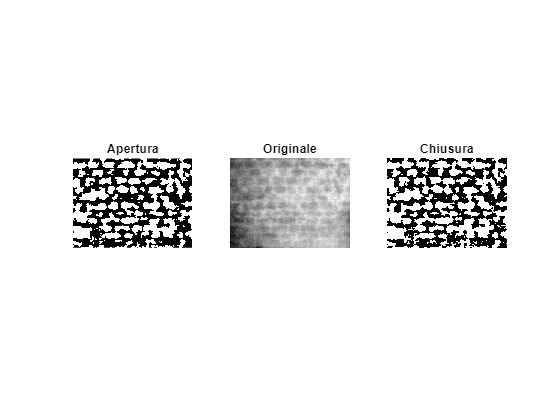

figure;
subplot(1,3,1);
imshow(result);
title("Apertura")
subplot(1,3,2);
img = imread("F\F1_IR000650.bmp");
imshow(img);
title("Originale")
subplot(1,3,3);
imshow(result2);
title("Chiusura")
saveas(gcf, 'subplot_immagini.bmp', 'bmp');

O=imread("F\F6_IR000676.bmp");
SK=imread("half_F_SK\half_F6_IR000676.bmp_SK-w=20_r=2.bmp");
img=imread("half_F\half_F6_IR000676.bmp");
NN=imresize(img,2,'nearest');
Bil=imresize(img,2,'bilinear');
Bic=imresize(img,2,'bicubic');
L3=imresize(img,2,'lanczos3');
L2=imresize(img,2,'lanczos2');
psnr(O,SK)

ans = 36.6596

psnr(NN,O)

ans = 36.7539

psnr(L3,O)

ans = 37.9948

psnr(L2,O)

ans = 38.1974

psnr(Bic,O)

ans = 38.2061

psnr(Bil,O)

ans = 38.3515

% Calcolo delle componenti connesse
cc = bwconncomp(img);

% Numero totale di componenti connesse
numeroComponentiConnesse = cc.NumObjects

numeroComponentiConnesse = 93

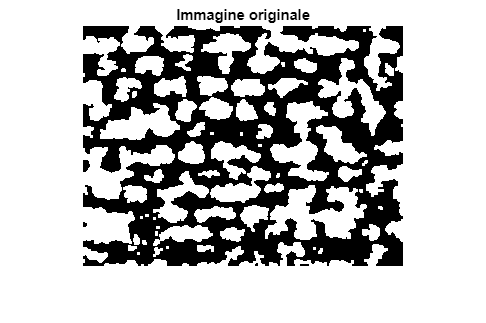

% Conversione dell'immagine etichettata in un'immagine colorata
%immagineColorata = label2rgb(etichette);

% Visualizzazione dell'immagine originale e dell'immagine con le componenti connesse colorate
imshow(img);
title('Immagine originale');

% Calcolo delle aree delle componenti connesse
aree = cellfun(@numel, cc.PixelIdxList);

% Soglia per la dimensione minima delle componenti connesse
sogliaAreaMinima = 100;

% Selezione delle componenti connesse più grandi della soglia
indiciComponentiSelezionate = find(aree >= sogliaAreaMinima);

% Creazione di un'immagine binaria con solo le componenti connesse selezionate
immagineSelezionata = ismember(labelmatrix(cc), indiciComponentiSelezionate);

name = pwd + "\100_inverted.bmp"

name = "C:\Users\nicolò\Documents\GitHub\lab_vuln_sismica\100_inverted.bmp"

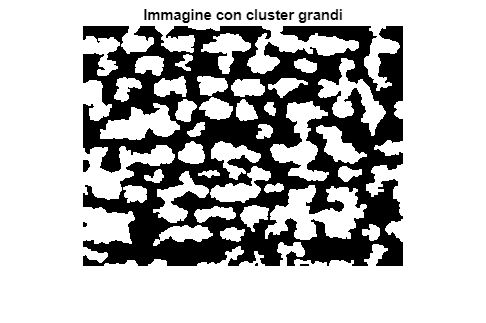


imwrite(immagineSelezionata, name);
imshow(immagineSelezionata);
title('Immagine con cluster grandi');


% Calcolo delle componenti connesse
cc = bwconncomp(immagineSelezionata);

% Numero totale di componenti connesse
%numeroComponentiConnesse = cc.NumObjects;
%disp(['Numero di componenti connesse: ' num2str(numeroComponentiConnesse)]);
% Etichettatura delle componenti connesse
etichette = labelmatrix(cc);

% Conversione dell'immagine etichettata in un'immagine colorata
immagineColorata = label2rgb(etichette);

% Numero totale di componenti connesse
numeroComponentiConnesse = cc.NumObjects

numeroComponentiConnesse = 56

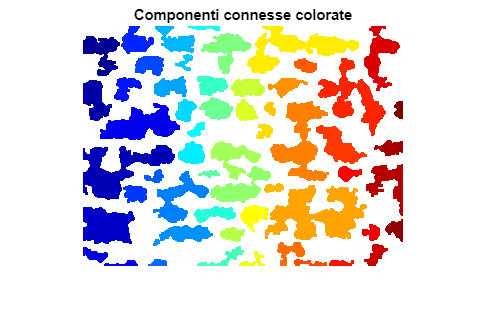


imshow(immagineColorata);
title('Componenti connesse colorate');

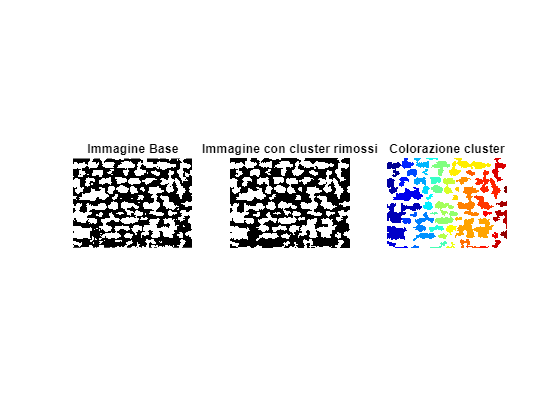

figure;
subplot(1,3,1);
imshow(result2);
title("Immagine Base");
subplot(1,3,2);
imshow(immagineSelezionata);
title("Immagine con cluster rimossi");
subplot(1,3,3);
imshow(immagineColorata);
title("Colorazione cluster");
saveas(gcf, 'subplot_immagini.bmp', 'bmp');

%DA MODIFICARE RISPETTO AL PATH DELLA CARTELLA DA USARE!!
path=string(pwd)+"\F\";
ext=".bmp";
inverted=false;
%DA MODIFICARE RISPETTO ALLA GRANDEZZA DELLE IMMAGINI NON DIMEZZATE
img_size=240;
files = dir(path + '*.bmp');
    for file = files'
        img = imread(path + file.name);
        if (size(img, 1) < img_size)
            method_names = {'nearest', 'bilinear', 'bicubic', 'lanczos2', 'lanczos3'};
            for i = 1:5
                result = phase_separation(img, false, true, method_names(i));
                name = file.name(1:end-4);
                name = path + name + "_phase_separation_" + method_names(i) + ext;
                imwrite(result, name);
                name = file.name(1:end-4);
                % Calcolo delle componenti connesse
                cc = bwconncomp(result);
                % Etichettatura delle componenti connesse
                etichette = labelmatrix(cc);
                name = path + name + "_phase_separation_" + method_names(i) + "separazione_fasi"+ext;
                % Conversione dell'immagine etichettata in un'immagine colorata
                immagineColorata = label2rgb(etichette);
                imwrite(immagineColorata, name);
            end
        else
            result = phase_separation(img, inverted);
            disp(file.name);
            name = file.name(1:end-4);
            name = path + name + "_phase_separation"+ext;
            imwrite(result, name);
            name = file.name(1:end-4);
            % Calcolo delle componenti connesse
            cc = bwconncomp(result);

            numeroComponentiConnesse = cc.NumObjects;
            disp('Componenti trovate senza sogliatura')
            disp(numeroComponentiConnesse);

            % Calcolo delle aree delle componenti connesse
            aree = cellfun(@numel, cc.PixelIdxList);
            
            % Soglia per la dimensione minima delle componenti connesse
            sogliaAreaMinima = 100;
            
            % Selezione delle componenti connesse più grandi della soglia
            indiciComponentiSelezionate = find(aree >= sogliaAreaMinima);
            
            % Creazione di un'immagine binaria con solo le componenti connesse selezionate
            immagineSelezionata = ismember(labelmatrix(cc), indiciComponentiSelezionate);
            
            % Calcolo delle componenti connesse
            cc = bwconncomp(immagineSelezionata);

            % Numero totale di componenti connesse
            numeroComponentiConnesse = cc.NumObjects;
            disp('Componenti trovate con sogliatura')
            disp(numeroComponentiConnesse);

            total_pixel = size(immagineSelezionata,1) * size(immagineSelezionata,2);
            pixel_bianchi = nnz(immagineSelezionata);
            disp('Percentuale pixel bianchi immagine sogliata')
            disp((pixel_bianchi / total_pixel) * 100);

            % Etichettatura delle componenti connesse
            %etichette = labelmatrix(cc);
            name = path + name + "_phase_separation_not_inverted"+ext;
            % Conversione dell'immagine etichettata in un'immagine colorata
            %immagineColorata = label2rgb(etichette);
            imwrite(immagineSelezionata, name);
        end
    end

F1_IR000650.bmp


Componenti trovate senza sogliatura


    78



Componenti trovate con sogliatura


    28



Percentuale pixel bianchi immagine sogliata


   49.0260



F2_IR000654.bmp


Componenti trovate senza sogliatura


    74



Componenti trovate con sogliatura


    29



Percentuale pixel bianchi immagine sogliata


   52.1146



F3_IR000659.bmp


Componenti trovate senza sogliatura


    67



Componenti trovate con sogliatura


    14



Percentuale pixel bianchi immagine sogliata


   51.5612



F4_IR000661.bmp


Componenti trovate senza sogliatura


    70



Componenti trovate con sogliatura


    18



Percentuale pixel bianchi immagine sogliata


   51.9831



F5_IR000667.bmp


Componenti trovate senza sogliatura


    91



Componenti trovate con sogliatura


    38



Percentuale pixel bianchi immagine sogliata


   49.2721



F6_IR000676.bmp


Componenti trovate senza sogliatura


    80



Componenti trovate con sogliatura


    23



Percentuale pixel bianchi immagine sogliata


   50.5716



%DA MODIFICARE RISPETTO AL PATH DELLA CARTELLA DA USARE!!
path=string(pwd)+"\F_inverted\";
ext=".bmp";
inverted=true;
%DA MODIFICARE RISPETTO ALLA GRANDEZZA DELLE IMMAGINI NON DIMEZZATE
img_size=240;
files = dir(path + '*.bmp');
    for file = files'
        img = imread(path + file.name);
        if (size(img, 1) < img_size)
            method_names = {'nearest', 'bilinear', 'bicubic', 'lanczos2', 'lanczos3'};
            for i = 1:5
                result = phase_separation(img, false, true, method_names(i));
                name = file.name(1:end-4);
                name = path + name + "_phase_separation_" + method_names(i) + ext;
                imwrite(result, name);
                name = file.name(1:end-4);
                % Calcolo delle componenti connesse
                cc = bwconncomp(result);
                % Etichettatura delle componenti connesse
                etichette = labelmatrix(cc);
                name = path + name + "_phase_separation_" + method_names(i) + "separazione_fasi"+ext;
                % Conversione dell'immagine etichettata in un'immagine colorata
                immagineColorata = label2rgb(etichette);
                imwrite(immagineColorata, name);
            end
        else
            result = phase_separation(img, inverted);
            disp(file.name);
            name = file.name(1:end-4);
            name = path + name + "_phase_separation"+ext;
            imwrite(result, name);
            name = file.name(1:end-4);
            % Calcolo delle componenti connesse
            cc = bwconncomp(result);

            numeroComponentiConnesse = cc.NumObjects;
            disp('Componenti trovate senza sogliatura')
            disp(numeroComponentiConnesse);

            % Calcolo delle aree delle componenti connesse
            aree = cellfun(@numel, cc.PixelIdxList);
            
            % Soglia per la dimensione minima delle componenti connesse
            sogliaAreaMinima = 100;
            
            % Selezione delle componenti connesse più grandi della soglia
            indiciComponentiSelezionate = find(aree >= sogliaAreaMinima);
            
            % Creazione di un'immagine binaria con solo le componenti connesse selezionate
            immagineSelezionata = ismember(labelmatrix(cc), indiciComponentiSelezionate);
            

            % Calcolo delle componenti connesse
            cc = bwconncomp(immagineSelezionata);

            % Numero totale di componenti connesse
            numeroComponentiConnesse = cc.NumObjects;
            disp('Componenti trovate con sogliatura')
            disp(numeroComponentiConnesse);

            total_pixel = size(immagineSelezionata,1) * size(immagineSelezionata,2);
            pixel_bianchi = nnz(immagineSelezionata);
            disp('Percentuale pixel bianchi immagine sogliata')
            disp((pixel_bianchi / total_pixel) * 100);

            % Etichettatura delle componenti connesse
            %etichette = labelmatrix(cc);
            name = path + name + "_phase_separation_inverted"+ext;
            % Conversione dell'immagine etichettata in un'immagine colorata
            %immagineColorata = label2rgb(etichette);
            imwrite(immagineSelezionata, name);
        end
    end

F1_IR000650.bmp


Componenti trovate senza sogliatura


   128



Componenti trovate con sogliatura


    76



Percentuale pixel bianchi immagine sogliata


   45.5091



F2_IR000654.bmp


Componenti trovate senza sogliatura


   143



Componenti trovate con sogliatura


    82



Percentuale pixel bianchi immagine sogliata


   45.5404



F3_IR000659.bmp


Componenti trovate senza sogliatura


   126



Componenti trovate con sogliatura


    47



Percentuale pixel bianchi immagine sogliata


   48.7526



F4_IR000661.bmp


Componenti trovate senza sogliatura


   134



Componenti trovate con sogliatura


    65



Percentuale pixel bianchi immagine sogliata


   45.5872



F5_IR000667.bmp


Componenti trovate senza sogliatura


   134



Componenti trovate con sogliatura


    78



Percentuale pixel bianchi immagine sogliata


   46.3034



F6_IR000676.bmp


Componenti trovate senza sogliatura


   126



Componenti trovate con sogliatura


    72



Percentuale pixel bianchi immagine sogliata


   46.9154

